# **IO191 - Analog and Digital Loopback**

This example shows you how to do a loopback test with the IO191 I/O module to verify the analog and digital loopback functionality of some of the input and output channels.

The IO191 is a 16-bit analog module with either 8 single-ended or 4 differential analog inputs, 4 analog outputs and 16 digital I/O lines configurable as inputs or outputs, 8 of which can be individually software-selected as input or output.

The Simulink model features the [IO191 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io191_setup), [IO191 Analog input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io191_analog_input), [IO191 Analog output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io191_analog_output), [IO191 Digital input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io191_digital_input), and [IO191 Digital output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io191_digital_output) blocks.

## Test Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO191 I/O module installed

- Connector cable from the I/O module to the terminal board

- 1 x 2-way 17-pin M12 terminal board with jumper wires

### Loopback Wiring

This example can be used as a loopback test, where the Analog and Digital Outputs are wired back to the Analog and Digital Inputs. 

For this the following wiring is required:

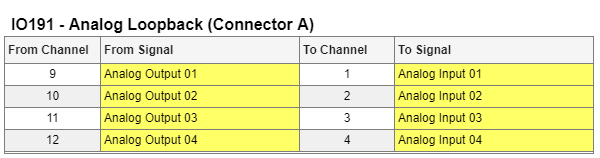

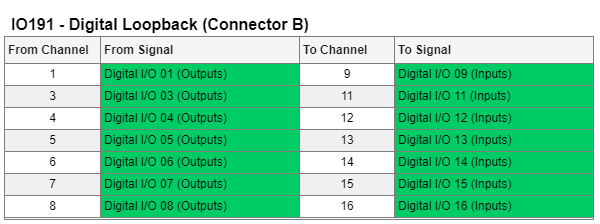

The full pin mapping of the IO191 can be found here: [IO191 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io191_pin_mapping)

## Open Simulink Model

 
modelName = 'sgMdl_IO191_AnalogDigitalLoopback';
open_system(modelName);         % Open Simulink model

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

Open the two Simulink scopes connected to the Analog and Digital input blocks and compare the signals to check if the loopback is working as expected. On the Analog Scope, four sine waves with different amplitudes must be displayed, and on the Digital scope, eight pulses:

  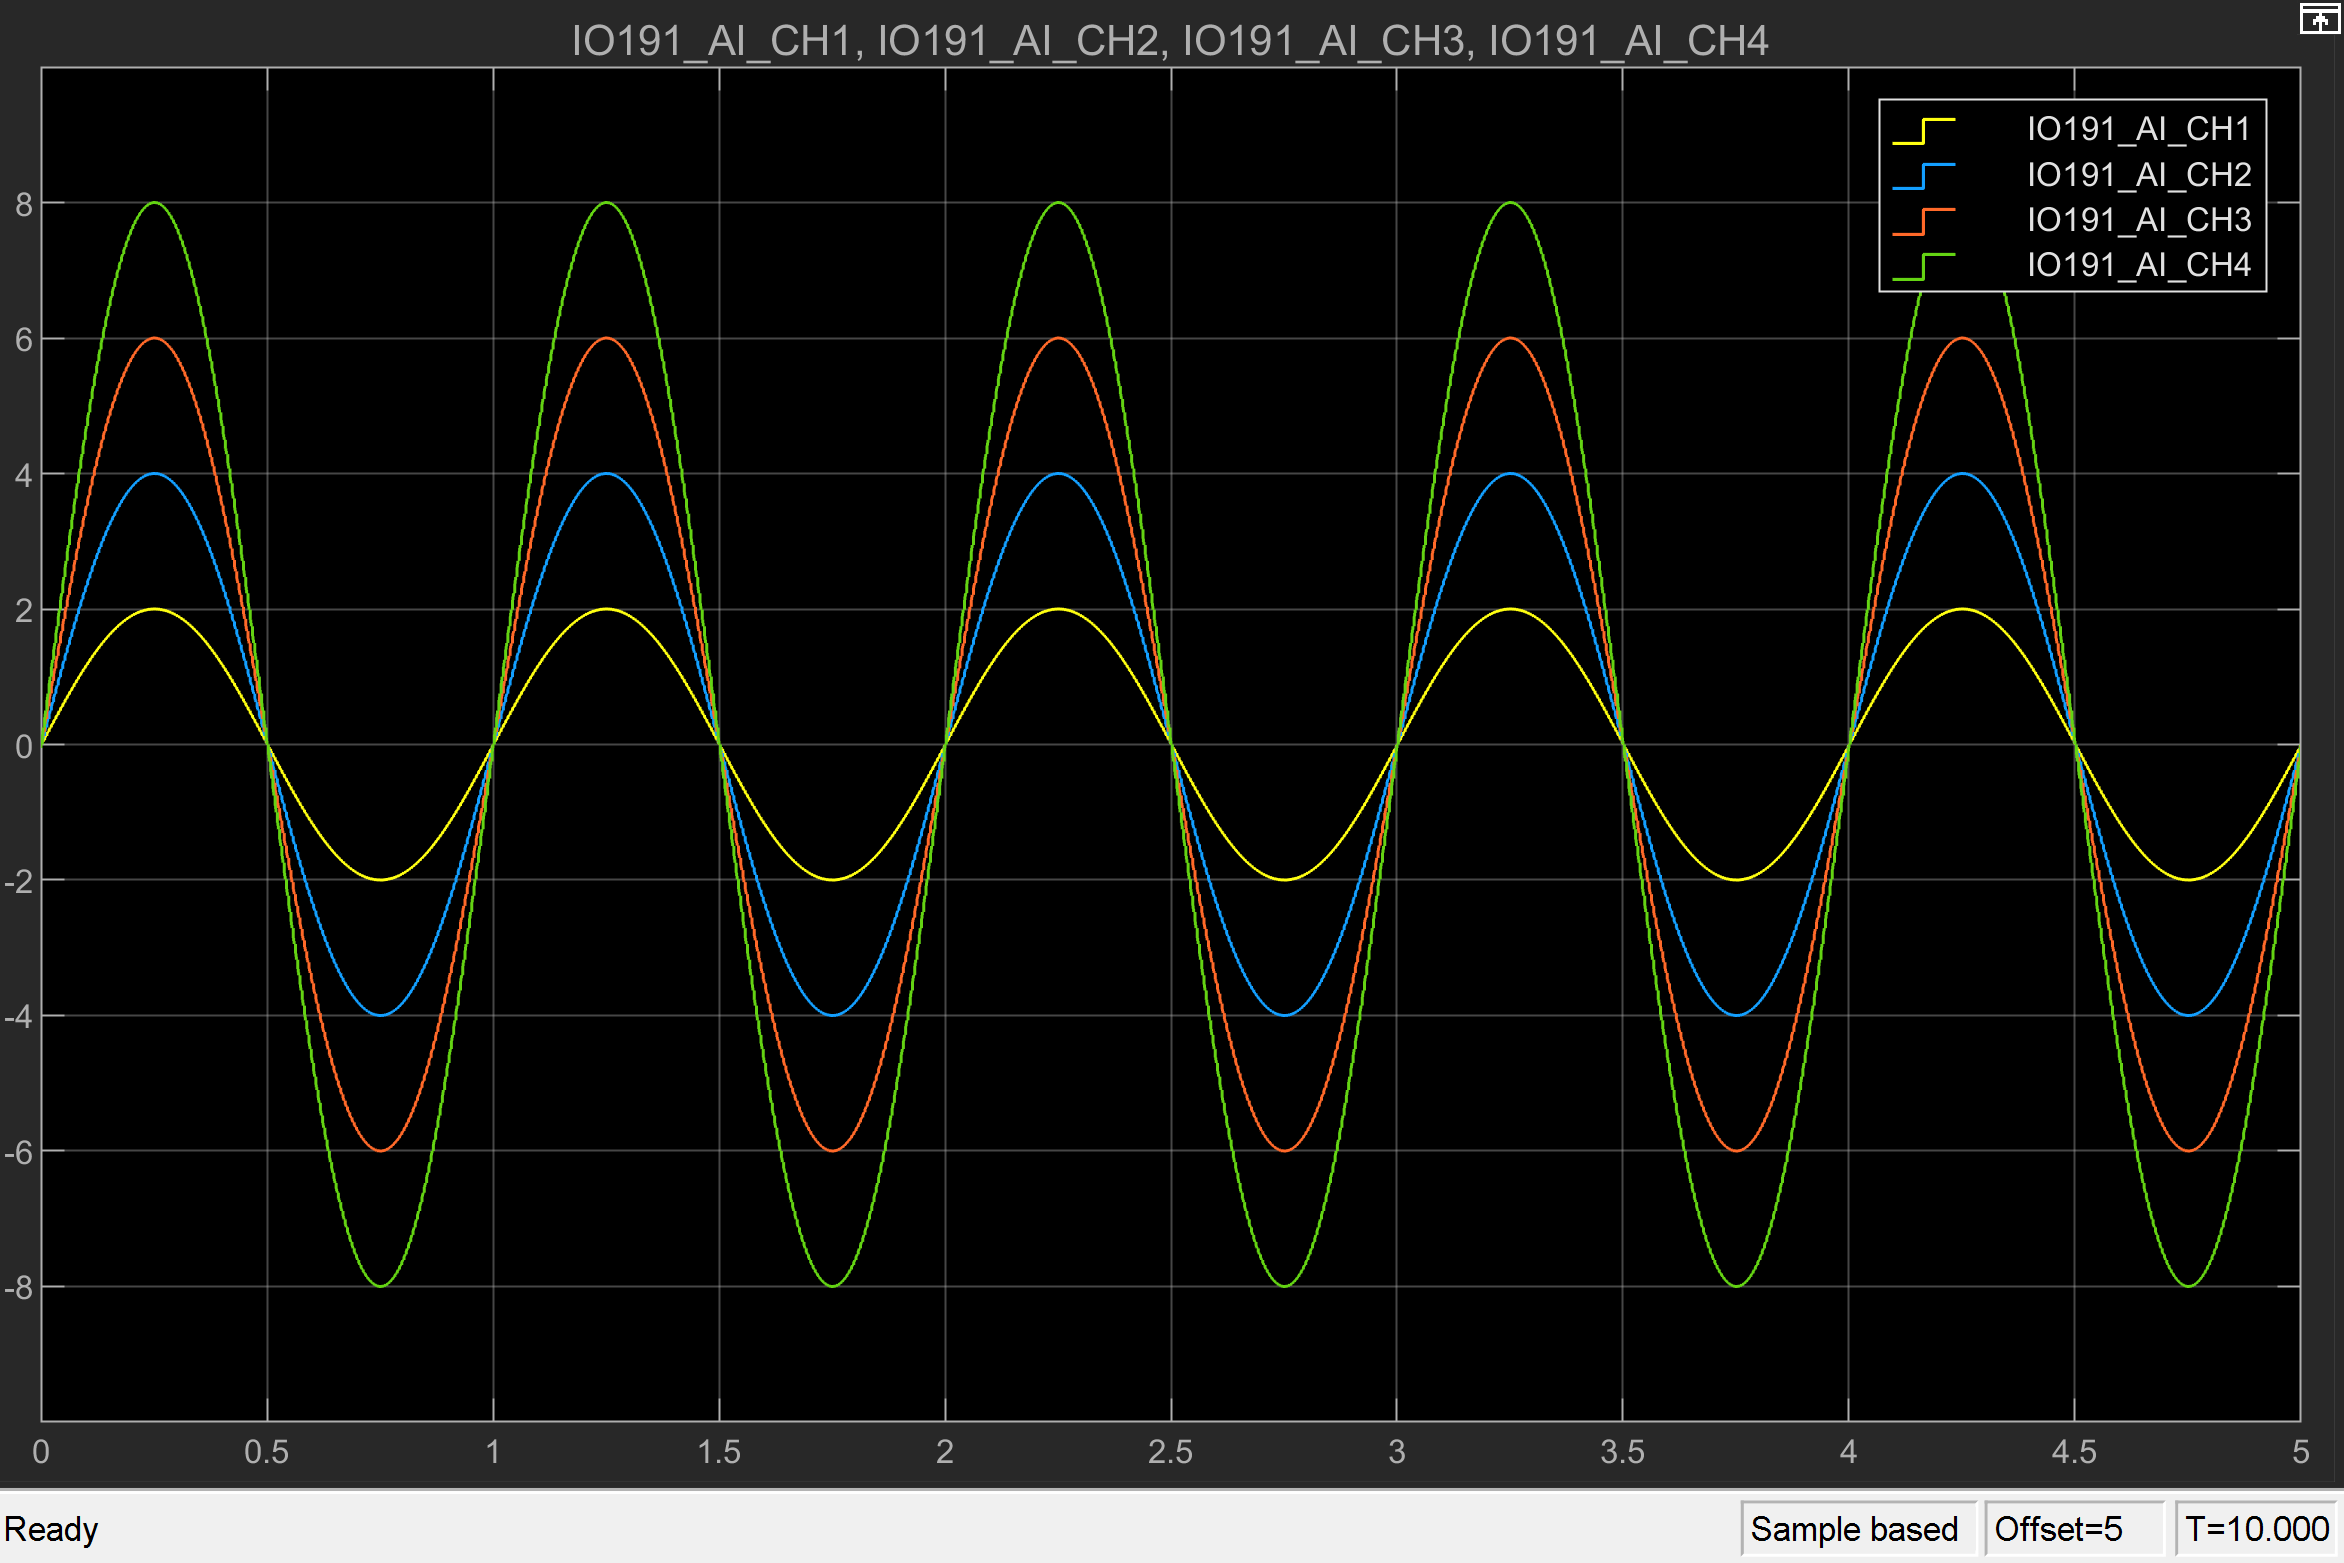

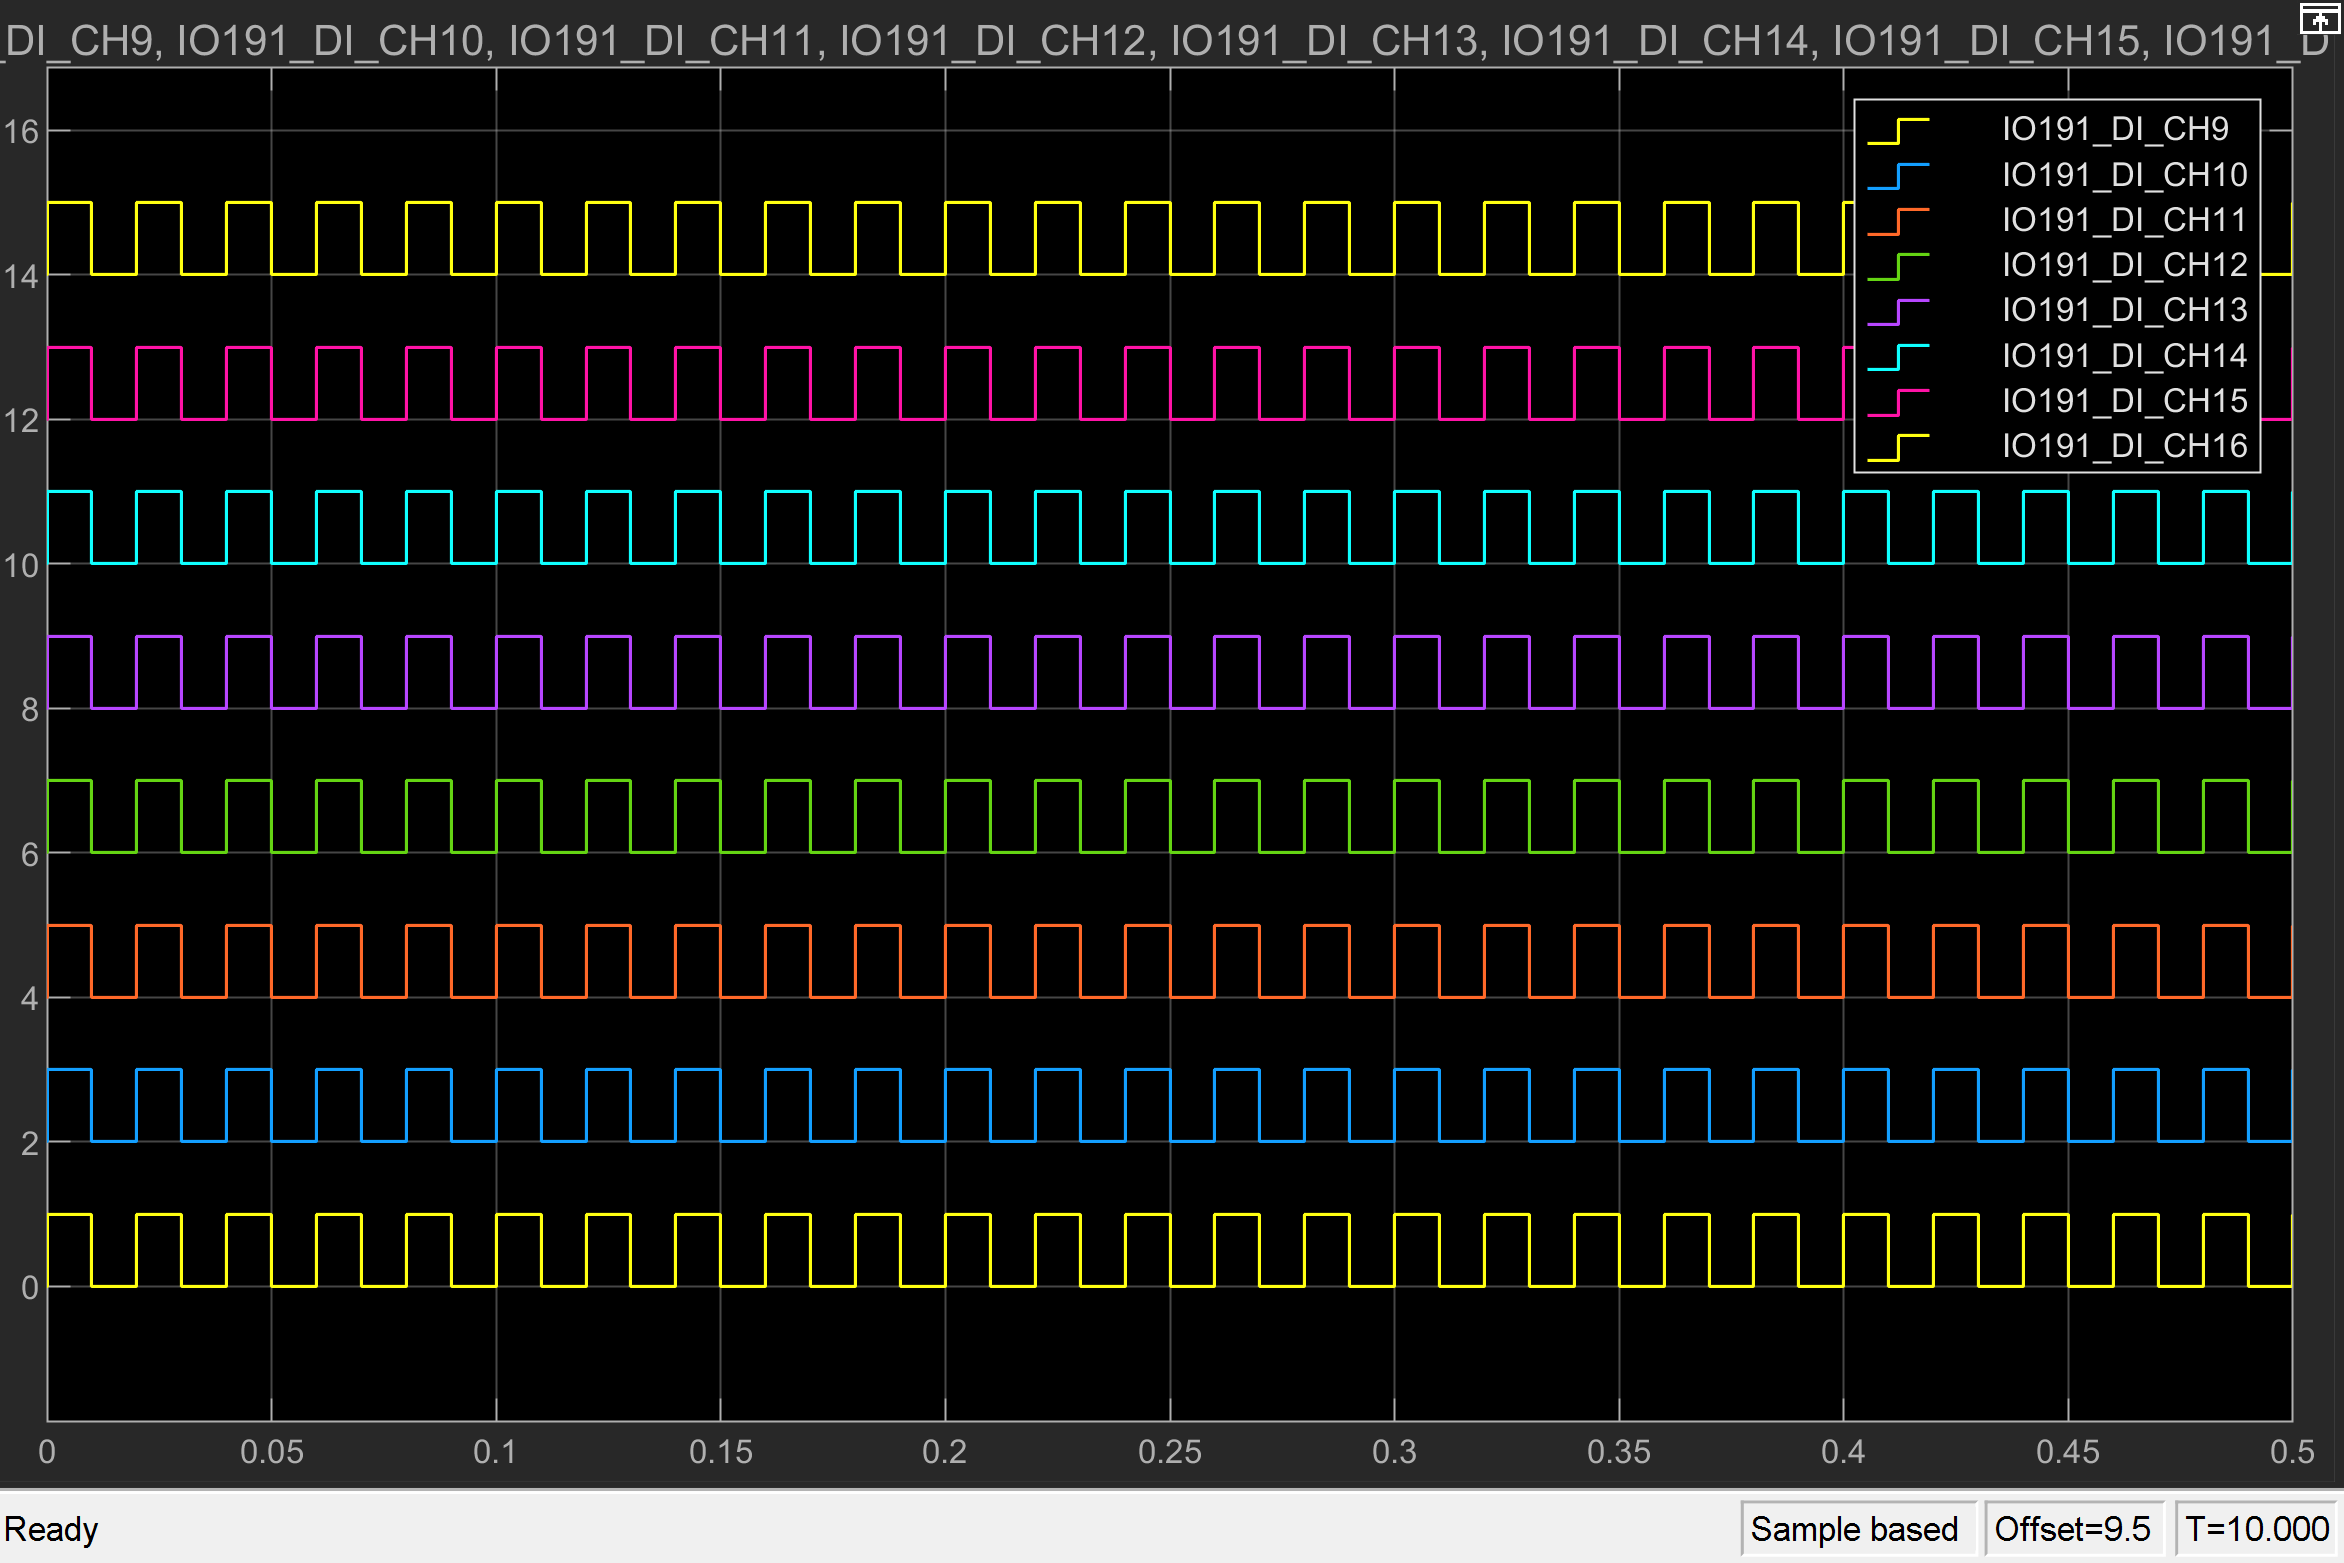

## Additional References

- [IO191 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io191)